clear; close all; clc;
addpath('functions/');

% xl=100;yl=100;
% load('hkdist_1e5.mat');
% rf=reshape(data(1:yl*xl),yl,xl);
% rf=rf-mean(rf(:));

lstmat=ls('beamformed/');lstmat=strcat('beamformed/',lstmat(3:end,:));
n=lstmat(3,:);
disp(n);

beamformed/rfscatt40um.mat 


load(n);


zlims=[1 20]*1e-3; % z axis
lims = zlims(1)<z & z<zlims(2);
rf=rf(lims,:);
zaxis=z(lims);xaxis=x;



env_rf=abs(hilbert(rf));
[a_0,b_0,z]=getab(env_rf);
z=round(z);
z(z<0)=0;z(255<z)=255;

roi=env_rf(1800:3200,60:70);roi=roi(:);
R=mean(roi)/std(roi)

R = 1.8088

S=skewness(roi)

S = 0.9052

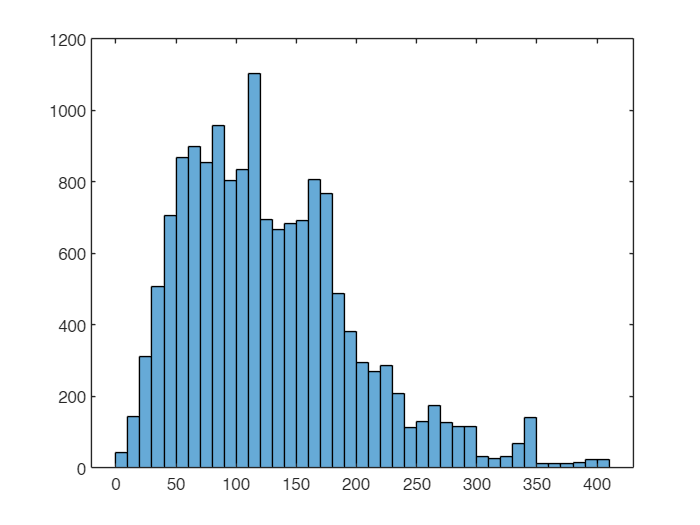

figure;histogram(roi)

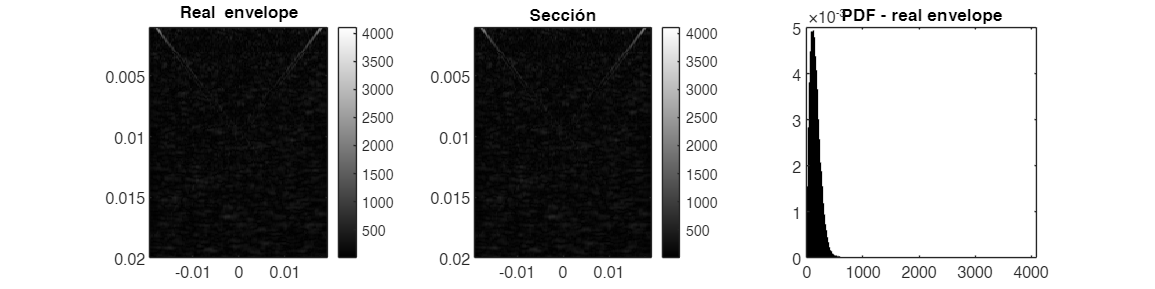

f=figure;f.Position=f.Position.*[1 1 3 1];
subplot(1,3,1);imagesc(xaxis,zaxis,env_rf);
title('\bfReal envelope');colormap gray;colorbar;%axis image;

subplot(1,3,2);imagesc(xaxis,zaxis,env_rf);
title('Sección');colormap gray;colorbar;%axis image;

subplot(1,3,3);histogram(env_rf,Normalization='pdf');
title('PDF - real envelope');axis square;

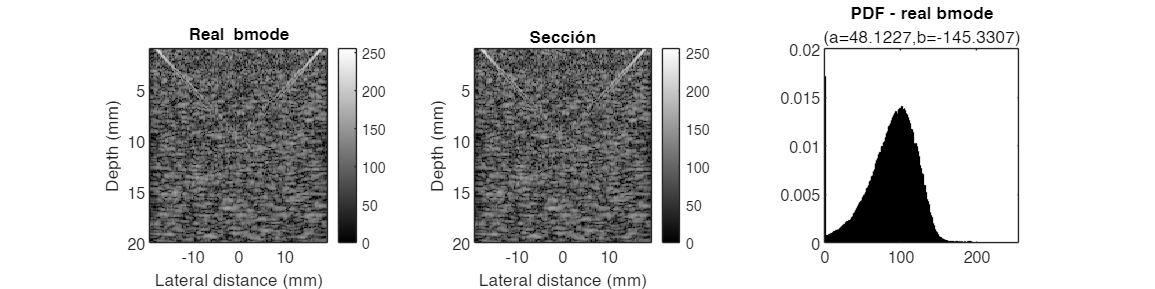



f=figure;f.Position=f.Position.*[1 1 3 1];
subplot(1,3,1);imagesc(xaxis*1e3,zaxis*1e3,z);
colormap gray;colorbar;clim([0 255]);%axis image;
title('\bfReal bmode');xlabel('Lateral distance (mm)');ylabel('Depth (mm)');

subplot(1,3,2);imagesc(xaxis*1e3,zaxis*1e3,z);
colormap gray;colorbar;clim([0 255]);%axis image;
title('Sección');xlabel('Lateral distance (mm)');ylabel('Depth (mm)');

subplot(1,3,3);histogram(z,Normalization='pdf');axis square;xlim([-Inf 255]);
title('PDF - real bmode',['(a=',num2str(a_0),',b=',num2str(b_0),')']);

%%%%%%%%% IMPLEMENTACIÓN 1 %%%%%%%%%
sigma=std(z(:));
mu=mean(z(:));
gamma=double(eulergamma);
psi=7000;

alpha=sqrt(24/pi^2*sigma^2);
% beta=mu-alpha/2*(log(2*psi)-gamma);
beta=b_0;

y1=exp((z-beta)/alpha);
D_seabra1=alpha;

%%%%%%%%% IMPLEMENTACIÓN 2 %%%%%%%%%

% n=41; m=n; L=n*m;

n=14;
% d=zeros(100,1);
% for n=1:100
m=n; L=n*m;
% a
ni=(n-1)/2;mj=(m-1)/2;
a_w=zeros(size(z,1)-2*ni,size(z,2)-2*mj);

for i=ni+1:size(z,1)-ni
for j=mj+1:size(z,2)-mj
    window = z(i-ni:i+ni, j-mj:j+mj);
    sigma = std(window,0,'all');

    % a
    a_w(i-ni,j-mj) = sigma;
end
end
a=sqrt(24)/pi*mean(a_w,'all');
% d(n)=a;
% end

% % b
% % s_w=zeros(size(z,1)-2*ni,size(z,2)-2*mj);
% b_w=zeros(size(z,1)-2*ni,size(z,2)-2*mj);
% for i=ni+1:size(z,1)-ni
% for j=mj+1:size(z,2)-mj
%     window = z(i-ni:i+ni, j-mj:j+mj);
%     sigma = std(window,0,'all');
% 
%     % s
%     % s_w(i-ni,j-mj) = min(window,[],'all');
%     s = min(window,[],'all');
% 
%     % b
%     b_k=zeros(1,L);
%     for k=1:L
%         b_i_j_k= k*s/(L-1);
%         t=exp((s-b_i_j_k)/a)-1;
%         p=L/(a*sigma^2) * t*(t+1) * exp(-L/(2*sigma^2)*t^2);
% 
%         b_k(k) = b_i_j_k * p;
%     end
%     b_w(i-ni,j-mj)=sum(b_k);
% end
% end
% b=mean(b_w,'all');
b=b_0;

y2=exp((z-b_0)/a);
D_seabra2=a;

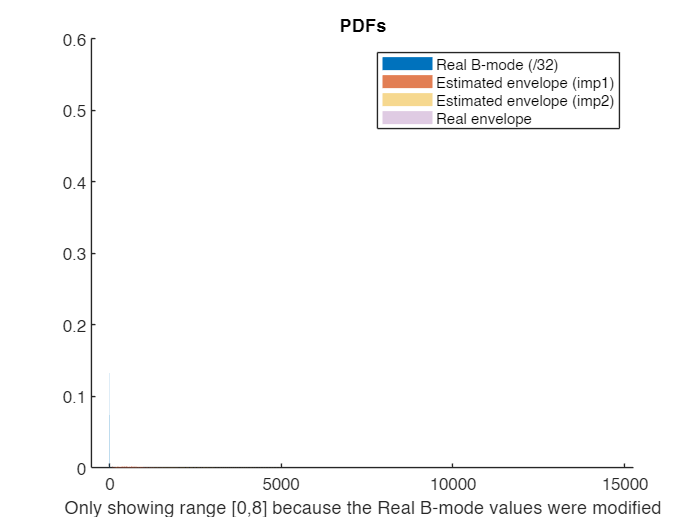

figure;hold on;
histogram(z/32,Normalization='pdf',FaceAlpha=1,EdgeAlpha=0);
histogram(y1,Normalization='pdf',FaceAlpha=0.75,EdgeAlpha=0);
histogram(y2,Normalization='pdf',FaceAlpha=0.5,EdgeAlpha=0);
histogram(env_rf,Normalization='pdf',FaceAlpha=0.25,EdgeAlpha=0);
xlabel('Only showing range [0,8] because the Real B-mode values were modified')
title('PDFs');
legend('Real B-mode (/32)','Estimated envelope (imp1)','Estimated envelope (imp2)','Real envelope');

alabel={'True value';'seabra2008modeling';'seabra2011rf'};
avalues=[a_0;D_seabra1;D_seabra2];
disp('Valores de a');

Valores de a


table(alabel,avalues)

ans = 3×2 table
            alabel            avalues
    ______________________    _______

    {'True value'        }    65.301 
    {'seabra2008modeling'}    68.397 
    {'seabra2011rf'      }     58.63 
